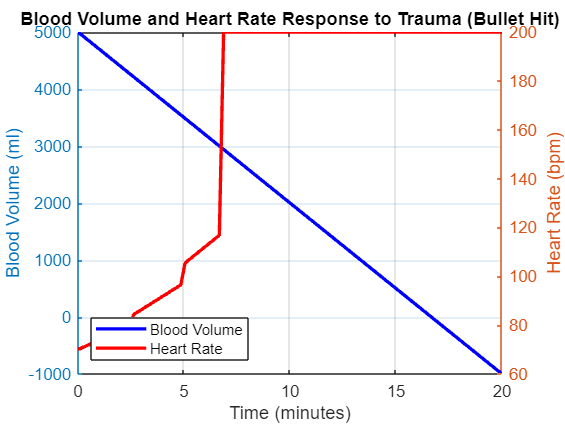

% Bullet Hit Simulation: Heart Rate and Blood Volume Change
% This code simulates heart rate (HR) response to blood volume loss due to trauma (bullet hit)

% Clear workspace and set parameters
clear; clc; close all;

% Define parameters for the simulation
total_blood_volume = 5000; % Total blood volume (ml) for a 70 kg person
blood_loss_rate = 300;     % Blood loss per minute (ml) (adjustable)
duration = 20;             % Simulation duration (minutes)
initial_hr = 70;           % Initial resting heart rate (bpm)
max_hr = 200;              % Maximum heart rate during severe shock (bpm)

% Blood volume thresholds for different stages of shock
mild_shock_threshold = 0.85 * total_blood_volume;  % 15% blood loss
moderate_shock_threshold = 0.70 * total_blood_volume; % 30% blood loss
severe_shock_threshold = 0.60 * total_blood_volume;   % 40% blood loss

% Create time vector (minutes)
time = linspace(0, duration, 100);

% Initialize arrays for blood volume and heart rate
blood_volume = total_blood_volume - blood_loss_rate * time; % Blood volume over time
heart_rate = zeros(1, length(time));  % Initialize heart rate array

% Simulate heart rate response based on blood volume
for i = 1:length(time)
    if blood_volume(i) >= mild_shock_threshold
        % Normal or mild shock: Small increase in heart rate
        heart_rate(i) = initial_hr + 0.5 * (max_hr - initial_hr) * (1 - blood_volume(i)/total_blood_volume);
    elseif blood_volume(i) >= moderate_shock_threshold
        % Moderate shock: Significant increase in heart rate
        heart_rate(i) = initial_hr + 0.7 * (max_hr - initial_hr) * (1 - blood_volume(i)/total_blood_volume);
    elseif blood_volume(i) >= severe_shock_threshold
        % Severe shock: Rapid increase in heart rate
        heart_rate(i) = initial_hr + 0.9 * (max_hr - initial_hr) * (1 - blood_volume(i)/total_blood_volume);
    else
        % Critical blood loss, heart rate reaching maximum
        heart_rate(i) = max_hr;
    end
end

% Plot the simulation results
figure;
yyaxis left;
plot(time, blood_volume, 'b', 'LineWidth', 2);
xlabel('Time (minutes)');
ylabel('Blood Volume (ml)');
title('Blood Volume and Heart Rate Response to Trauma (Bullet Hit)');
grid on;
hold on;

yyaxis right;
plot(time, heart_rate, 'r', 'LineWidth', 2);
ylabel('Heart Rate (bpm)');
legend('Blood Volume', 'Heart Rate', 'Location', 'SouthWest');
hold off;


% Display final heart rate and blood volume at end of simulation
fprintf('Final heart rate after %d minutes: %.2f bpm\n', duration, heart_rate(end));

Final heart rate after 20 minutes: 200.00 bpm


fprintf('Final blood volume after %d minutes: %.2f ml\n', duration, blood_volume(end));

Final blood volume after 20 minutes: -1000.00 ml
